# Perfect matching in bipartite graph

Assignment problem template

### Make all possible adjacency matrices of desired dimentions

clear();

sn =8;
tn =6;

maxd = max(tn,sn);
mind = min(tn,sn);

d = diag(ones(1, maxd));
p = perms([1:mind]);
i  = randi([1, size(p,1)]);


#### Amount of adjacency matrices

Amount = size(p,1)

Amount = 720

a = d(:, p([i],:));

adj_a = [zeros(maxd,maxd), zeros(maxd,mind);
         a', zeros(mind,mind)];

g = digraph(adj_a);

### Plot graph

h = plot(g);

#### Layout

h.XData(1:tn) = 1;
h.XData((tn+1):end) = 2;
h.YData(1:tn) = linspace(0,1,tn);
h.YData((tn+1):end) = linspace(0,1,sn);


#### Decor

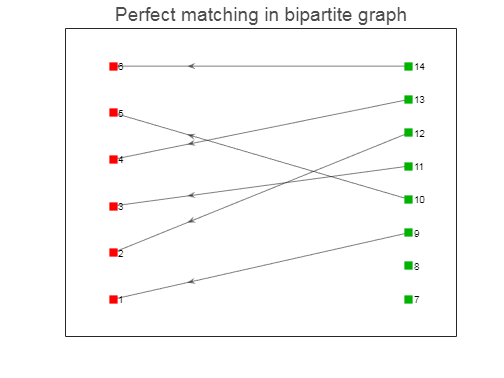

title('Perfect matching in bipartite graph', 'FontWeight','Normal','FontSize',16,'Color', [0.3 0.3 0.3]);

h.MarkerSize = 8;
h.Marker = 's';
h.ArrowPosition = 0.75;

tc = repmat([1 0 0 ], tn, 1);
sc = repmat([0 0.7 0 ], sn, 1);
h.NodeColor = [tc; sc];

h.EdgeColor = 'black';